## Iteration V

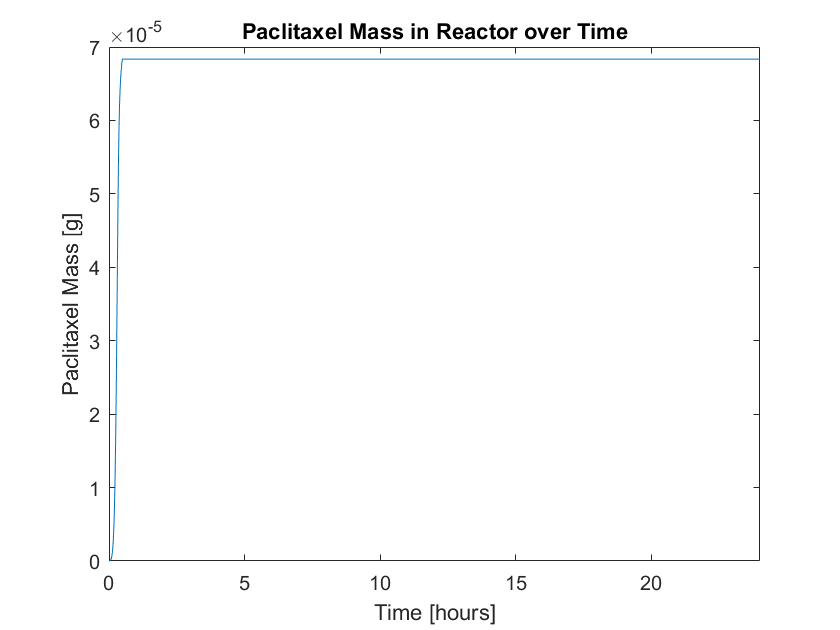

clear;
% Constants and Initial Conditions
V = 1; % [L]

e = 2; % [g/L]
s = 2; % [g/L]
rho_cell = 200; % [g/L]
rho_water = 1000; % g/L

x = 5; % [g/L]
p = 0; % [g/L]
d = 0; % [g/L]
a = 0; % [g/L]

Wx = 150.13; % [g/mol]
Wd = 272.476; % [g/mol]
Wa = 60.052; % [g/mol]
Wp = 853.906; % [g/mol]

kx_x5p = 0.065; % Voronsky
kx5p_gap = 0.57; % Lee
kgap_3pg = 0.891; % Yu
k3pg_pep = 0.078; % Mercade
kpep_pyr = 0.52; % Malcovati
kpyr_accoa = 0.134; % Inui
kaccoa_a = 0.885; % Liang

kaccoa_aacoa = 506; % Feigenbaum
kaacoa_3h3mg = 2; % Durr
k3h3mg_mv = 0.0035; % Middleton
kmv_m5p = 0.06; % Bloch
km5p_m5dp = 0.06; % Agranoff
km5dp_ipp = 0.00000133; % Gogerty
kp_dg3p_1ddx5p = 3; % Hahn
k1ddx5p_2cmde4p = 1.6; % Takenoya
k2cmde4p_4d2cmde = 23; % Richard
k4d2cmde_4d2cmde2p = 33; % Chesters
k4d2cmde2p_2cmde24c = 0.75; % Yu
k2cmde24c_1h2m2b4d = 0.99; % Zepeck
k1h2m2b4d_dmapp = 0.03; % Wolff

kdmapp_ipp_ggdp = 0.109; % Yu
kggdp_d = 0.003; % Jennewein

kd_t5a = 0.016; % Jennewein
kt5a_t5a13ad = 5.77; % Chau 
k2dbt_10db = 0.00635; % Nawarathne
k10db_b = 6.1; % Fang
kb_bpacoa_bpab = 2.2; % Walker
kbpab_ndbt = 0.0049; % Zhu
knbt_p = 0.0049; % Zhu

mumax_e = 0.76; % [1/h]
mumax_s = 0.5; % [1/h]
Kse = 0.00716; % [g/L]
Kss = 0.0000054; % [mol/L]
Yex = 0.57; % [g E coli / g xylose]
Ysa = 0.84; % [g S cerevisae / mol acetate]

time = 0:0.01:24; % [h]
p_t = zeros(length(time),1);
delt = 0.01;
for i = 1:length(time)
    p_t(i) = p; % [g]
    
    Vs1 = e * V / rho_cell; % [L] 
    Vs2 = s * V / rho_cell; % [L]
   
    rxd = (x / 3) * 60 * 1 / (1 / kx_x5p + 1 / kx5p_gap + 1 / kgap_3pg + 1 / k3pg_pep + 1 / kpep_pyr + 1 / kpyr_accoa + 1 / kaccoa_aacoa + 1 / kaacoa_3h3mg + 1 / k3h3mg_mv + 1 / kmv_m5p + 1 / km5p_m5dp + 1 / km5dp_ipp + 1 / kp_dg3p_1ddx5p + 1 / k1ddx5p_2cmde4p + 1 / k2cmde4p_4d2cmde + 1 / k4d2cmde_4d2cmde2p + 1 / k4d2cmde2p_2cmde24c + 1 / k2cmde24c_1h2m2b4d + 1 / k1h2m2b4d_dmapp + 1 / kdmapp_ipp_ggdp + kggdp_d); % [mol/L-h]
    rxa = (x / 3) * 60 * 1 / (1 / kx_x5p + 1 / kx5p_gap + 1 / kgap_3pg + 1 / k3pg_pep + 1 / kpep_pyr + 1 / kpyr_accoa + 1 / kaccoa_a); % [mol/L-h]
    rdp = d * 60 * 1 / (1 / kd_t5a + 1 / kt5a_t5a13ad + 1 / k2dbt_10db + 1 / k10db_b + 1 / kb_bpacoa_bpab + 1 / kbpab_ndbt + 1 / knbt_p); % [mol/L-h]
    rxe = (mumax_e * (x / 3)) / (Kse + (x / 3)) * (e * V / (Yex)); % [g/L-h]
    ras = (mumax_s * a) / (Kss + a) * (s * V / (Ysa / Wa)); % [g/L-h]
    
    if x < Wd / 6.02e23 % mass of one molecule of taxadiene
        rxd = 0;
        rxa = x / 2 * 60 * 1 / (1 / kx_x5p + 1 / kx5p_gap + 1 / kgap_3pg + 1 / k3pg_pep + 1 / kpep_pyr + 1 / kpyr_accoa + 1 / kaccoa_a); % [mol/L-h]
        rxe = mumax_e * (x / 2) / (Kse + (x / 3)) * e * V / (Yex); % [g/L-h]
    end
    if x < Wa / 6.02e23 % mass of one molecule of acetate
        rxa = 0;
        rxe = mumax_e * (x) / (Kse + (x / 3)) * e * V / (Yex); % [g/L-h]
    end
    if d < Wp / 6.02e23 % mass of one molecule of paclitaxel
        rdp = 0;
    end
    % integrate dxdt = F1 * C1 - (rxe + rxd + rxa) * Wx * Vs1; % [g/h]
    x = x - (rxe + rxd + rxa) * Wx * Vs1 * delt; % [g]
    if x < 0
        x = 0;
    end
    % integrate dddt = rxd * Wx * Vs1 - rdp * Wd * Vs2; % [g/h]
    d = d + rxd * Wx * Vs1 * delt - rdp * Wd * Vs2 * delt; % [g]
    if d < 0
        d = 0;
    end
    % integrate dadt = rxa * Wx * Vs1 - ras * Wa * Vs2; % [g/h]
    a = a + rxa * Wx * Vs1 * delt - ras * Wa * Vs2 * delt; % [g]
    if a < 0
        a = 0;
    end
    % integrate dedt = rxe * Wx * Vs1; % [g/h]
    e = e + rxe * delt; % [g]
    if e < 0
        e = 0;
    end
    % integrate dsdt = ras * Wa * Vs2; % [g/h]
    s = s + ras * delt; 
    if s < 0
        s = 0;
    end
    C2 = p / V; % [g/L]
    % integrate dpdt = rdp * Vs2 - F2 * C2
    p = p + rdp * Vs2 * Wd * delt; % [g]
    if p < 0
        p = 0;
    end
end

plot(time, p_t)
title('Paclitaxel Mass in Reactor over Time')
xlabel('Time [hours]')
xlim([0,24])
ylabel('Paclitaxel Mass [g]')

## Iteration VI

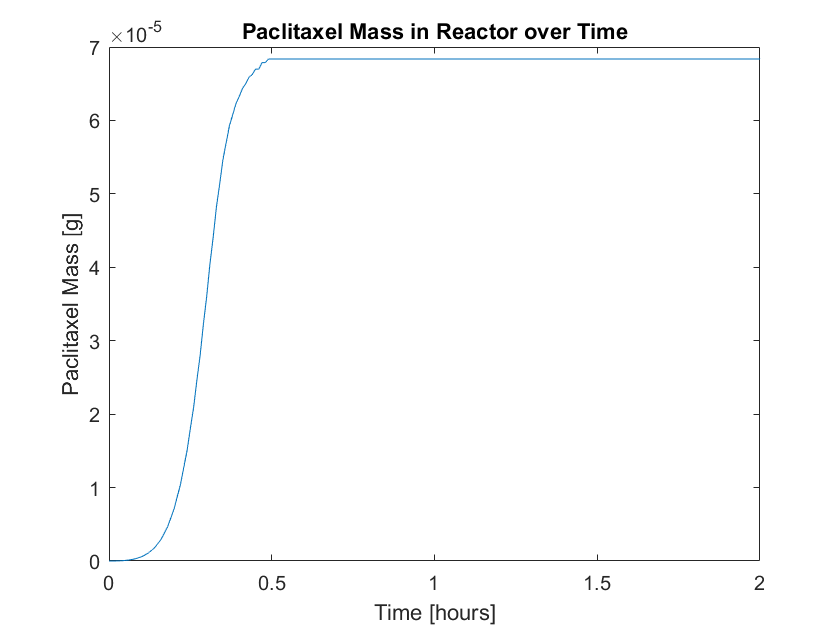

clear;
% Constants and Initial Conditions
V = 1; % [L]

e = 2; % [g/L]
s = 2; % [g/L]
rho_cell = 200; % [g/L]
rho_water = 1000; % g/L

x = 5; % [g/L]
p = 0; % [g/L]
d = 0; % [g/L]
a = 0; % [g/L]

Wx = 150.13; % [g/mol]
Wd = 272.476; % [g/mol]
Wa = 60.052; % [g/mol]
Wp = 853.906; % [g/mol]

kx_x5p = 0.065; % Voronsky
kx5p_gap = 0.57; % Lee
kgap_3pg = 0.891; % Yu
k3pg_pep = 0.078; % Mercade
kpep_pyr = 0.52; % Malcovati
kpyr_accoa = 0.134; % Inui
kaccoa_a = 0.885; % Liang

kaccoa_aacoa = 506; % Feigenbaum
kaacoa_3h3mg = 2; % Durr
k3h3mg_mv = 0.0035; % Middleton
kmv_m5p = 0.06; % Bloch
km5p_m5dp = 0.06; % Agranoff
km5dp_ipp = 0.00000133; % Gogerty
kp_dg3p_1ddx5p = 3; % Hahn
k1ddx5p_2cmde4p = 1.6; % Takenoya
k2cmde4p_4d2cmde = 23; % Richard
k4d2cmde_4d2cmde2p = 33; % Chesters
k4d2cmde2p_2cmde24c = 0.75; % Yu
k2cmde24c_1h2m2b4d = 0.99; % Zepeck
k1h2m2b4d_dmapp = 0.03; % Wolff

kdmapp_ipp_ggdp = 0.109; % Yu
kggdp_d = 0.003; % Jennewein

kd_t5a = 0.016; % Jennewein
kt5a_t5a13ad = 5.77; % Chau 
k2dbt_10db = 0.00635; % Nawarathne
k10db_b = 6.1; % Fang
kb_bpacoa_bpab = 2.2; % Walker
kbpab_ndbt = 0.0049; % Zhu
knbt_p = 0.0049; % Zhu

mumax_e = 0.76; % [1/h]
mumax_s = 0.5; % [1/h]
Kse = 0.00716; % [g/L]
Kss = 0.0000054; % [mol/L]
Yex = 0.57; % [g E coli / g xylose]
Ysa = 0.84; % [g S cerevisae / mol acetate]
Ki = 0.008; % [mol acetate / L]

time = 0:0.01:24; % [h]
p_t = zeros(length(time),1);
delt = 0.01;

for i = 1:length(time)
    p_t(i) = p; % [g]
    
    Vs1 = e * V / rho_cell; % [L] 
    Vs2 = s * V / rho_cell; % [L]
    
    rxd = (x / 3) * 60 * 1 / (1 / kx_x5p + 1 / kx5p_gap + 1 / kgap_3pg + 1 / k3pg_pep + 1 / kpep_pyr + 1 / kpyr_accoa + 1 / kaccoa_aacoa + 1 / kaacoa_3h3mg + 1 / k3h3mg_mv + 1 / kmv_m5p + 1 / km5p_m5dp + 1 / km5dp_ipp + 1 / kp_dg3p_1ddx5p + 1 / k1ddx5p_2cmde4p + 1 / k2cmde4p_4d2cmde + 1 / k4d2cmde_4d2cmde2p + 1 / k4d2cmde2p_2cmde24c + 1 / k2cmde24c_1h2m2b4d + 1 / k1h2m2b4d_dmapp + 1 / kdmapp_ipp_ggdp + kggdp_d); % [mol/L-h]
    rxa = (x / 3) * 60 * 1 / (1 / kx_x5p + 1 / kx5p_gap + 1 / kgap_3pg + 1 / k3pg_pep + 1 / kpep_pyr + 1 / kpyr_accoa + 1 / kaccoa_a); % [mol/L-h]
    rdp = d * 60 * 1 / (1 / kd_t5a + 1 / kt5a_t5a13ad + 1 / k2dbt_10db + 1 / k10db_b + 1 / kb_bpacoa_bpab + 1 / kbpab_ndbt + 1 / knbt_p); % [mol/L-h]
    rxe = mumax_e * (x / 3) / (Kse * (1 + a / (Ki * Wa)) + (x / 3)) * e * V / (Yex); % [g/L-h]
    ras = mumax_s * a / (Kss + a) * s * V / (Ysa / Wa); % [g/L-h]
    
    if x < Wd / 6.02e23 % mass of one molecule of taxadiene
        rxd = 0;
        rxa = x / 2 * 60 * 1 / (1 / kx_x5p + 1 / kx5p_gap + 1 / kgap_3pg + 1 / k3pg_pep + 1 / kpep_pyr + 1 / kpyr_accoa + 1 / kaccoa_a); % [mol/L-h]
        rxe = mumax_e * (x / 2) / (Kse * (1 + a / (Ki * Wa)) + (x / 2)) * e * V / (Yex); % [g/L-h]
    end
    if x < Wa / 6.02e23 % mass of one molecule of acetate
        rxa = 0;
        rxe = mumax_e * (x) / (Kse * (1 + a / (Ki * Wa)) + (x)) * e * V / (Yex); % [g/L-h]
    end
    if d < Wp / 6.02e23 % mass of one molecule of paclitaxel
        rdp = 0;
    end
    % integrate dxdt = F1 * C1 - (rxe + rxd + rxa) * Wx * Vs1; % [g/h]
    x = x - (rxe + rxd + rxa) * Wx * Vs1 * delt; % [g]
    if x < 0
        x = 0;
    end
    % integrate dddt = rxd * Wx * Vs1 - rdp * Wd * Vs2; % [g/h]
    d = d + rxd * Wx * Vs1 * delt - rdp * Wd * Vs2 * delt; % [g]
    if d < 0
        d = 0;
    end
    % integrate dadt = rxa * Wx * Vs1 - ras * Wa * Vs2; % [g/h]
    a = a + rxa * Wx * Vs1 * delt - ras * Wa * Vs2 * delt; % [g]
    if a < 0
        a = 0;
    end
    % integrate dedt = rxe * Wx * Vs1; % [g/h]
    e = e + rxe * delt; % [g]
    if e < 0
        e = 0;
    end
    % integrate dsdt = ras * Wa * Vs2; % [g/h]
    s = s + ras * delt; 
    if s < 0
        s = 0;
    end
    C2 = p / V; % [g/L]
    % integrate dpdt = rdp * Vs2 - F2 * C2
    p = p + rdp * Vs2 * Wd * delt; % [g]
    if p < 0
        p = 0;
    end
end

plot(time, p_t)
title('Paclitaxel Mass in Reactor over Time')
xlabel('Time [hours]')
xlim([0,2])
ylabel('Paclitaxel Mass [g]')

## Iteration VI

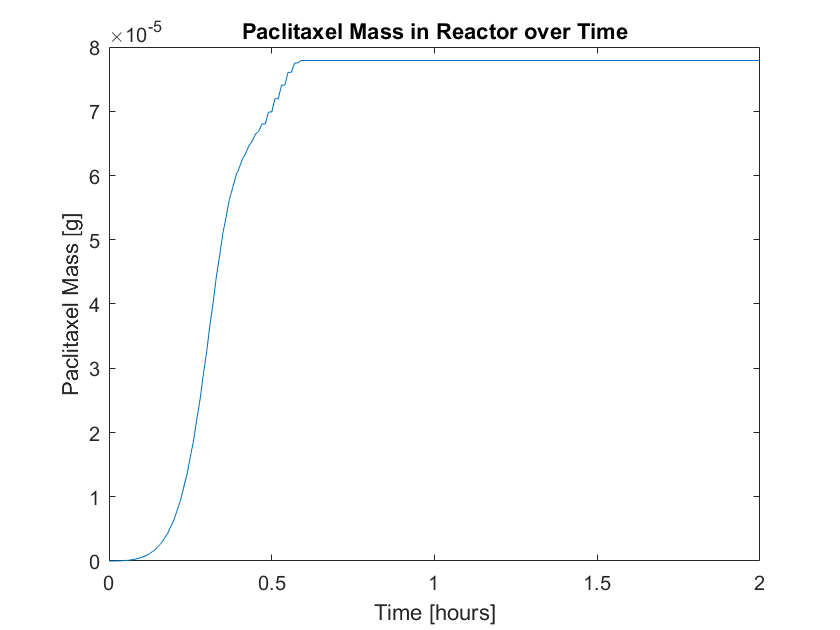

clear;
% Constants and Initial Conditions
V = 1; % [L]

e = 2; % [g/L]
s = 2; % [g/L]
rho_cell = 200; % [g/L]

x = 5; % [g/L]
p = 0; % [g/L]
d = 0; % [g/L]
a = 0; % [g/L]

Wx = 150.13; % [g/mol]
Wd = 272.476; % [g/mol]
Wa = 60.052; % [g/mol]
Wp = 853.906; % [g/mol]

kx_x5p = 0.065; % Voronsky
kx5p_gap = 0.57; % Lee
kgap_3pg = 0.891; % Yu
k3pg_pep = 0.078; % Mercade
kpep_pyr = 0.52; % Malcovati
kpyr_accoa = 0.134; % Inui
kaccoa_a = 0.885; % Liang

kaccoa_aacoa = 506; % Feigenbaum
kaacoa_3h3mg = 2; % Durr
k3h3mg_mv = 0.0035; % Middleton
kmv_m5p = 0.06; % Bloch
km5p_m5dp = 0.06; % Agranoff
km5dp_ipp = 0.00000133; % Gogerty
kp_dg3p_1ddx5p = 3; % Hahn
k1ddx5p_2cmde4p = 1.6; % Takenoya
k2cmde4p_4d2cmde = 23; % Richard
k4d2cmde_4d2cmde2p = 33; % Chesters
k4d2cmde2p_2cmde24c = 0.75; % Yu
k2cmde24c_1h2m2b4d = 0.99; % Zepeck
k1h2m2b4d_dmapp = 0.03; % Wolff

kdmapp_ipp_ggdp = 0.109; % Yu
kggdp_d = 0.003; % Jennewein

kd_t5a = 0.016; % Jennewein
kt5a_t5a13ad = 5.77; % Chau 
k2dbt_10db = 0.00635; % Nawarathne
k10db_b = 6.1; % Fang
kb_bpacoa_bpab = 2.2; % Walker
kbpab_ndbt = 0.0049; % Zhu
knbt_p = 0.0049; % Zhu

mumax_e = 0.76; % [1/h]
mumax_s = 0.5; % [1/h]
Kse = 0.00716; % [g/L]
Kss = 0.0000054; % [mol/L]
Yex = 0.57; % [g E coli / g xylose]
Ysa = 0.84; % [g S cerevisae / mol acetate]
Ki = 0.008; % [mol acetate / L]

alpha = 0.5; 

time = 0:0.01:24; % [h]
p_t = zeros(length(time),1);
delt = 0.01;

for i = 1:length(time)
    p_t(i) = p; % [g]
    
    Vs1 = e * V / rho_cell; % [L] 
    Vs2 = s * V / rho_cell; % [L]
   
    rxd = (x / 3) * 60 * 1 / (1 / kx_x5p + 1 / kx5p_gap + 1 / kgap_3pg + 1 / k3pg_pep + 1 / kpep_pyr + 1 / kpyr_accoa + 1 / kaccoa_aacoa + 1 / kaacoa_3h3mg + 1 / k3h3mg_mv + 1 / kmv_m5p + 1 / km5p_m5dp + 1 / km5dp_ipp + 1 / kp_dg3p_1ddx5p + 1 / k1ddx5p_2cmde4p + 1 / k2cmde4p_4d2cmde + 1 / k4d2cmde_4d2cmde2p + 1 / k4d2cmde2p_2cmde24c + 1 / k2cmde24c_1h2m2b4d + 1 / k1h2m2b4d_dmapp + 1 / kdmapp_ipp_ggdp + kggdp_d); % [mol/L-h]
    rxa = (x / 3) * 60 * 1 / (1 / kx_x5p + 1 / kx5p_gap + 1 / kgap_3pg + 1 / k3pg_pep + 1 / kpep_pyr + 1 / kpyr_accoa + 1 / kaccoa_a); % [mol/L-h]
    rdp = d * 60 * 1 / (1 / kd_t5a + 1 / kt5a_t5a13ad + 1 / k2dbt_10db + 1 / k10db_b + 1 / kb_bpacoa_bpab + 1 / kbpab_ndbt + 1 / knbt_p); % [mol/L-h]
    rxe = mumax_e * (x / 3) / (Kse * (1 + a / (Ki * Wa)) + (x / 3)) * e * V / (Yex); % [g/L-h]
    ras = mumax_s * a / (Kss + a) * s * V / (Ysa / Wa); % [g/L-h]
    
    if x < Wd / 6.02e23 % mass of one molecule of taxadiene
        rxd = 0;
        rxa = x / 2 * 60 * 1 / (1 / kx_x5p + 1 / kx5p_gap + 1 / kgap_3pg + 1 / k3pg_pep + 1 / kpep_pyr + 1 / kpyr_accoa + 1 / kaccoa_a); % [mol/L-h]
        rxe = mumax_e * (x / 2) / (Kse * (1 + a / (Ki * Wa)) + (x / 2)) * e * V / (Yex); % [g/L-h]
    end
    if x < Wa / 6.02e23 % mass of one molecule of acetate
        rxa = 0;
        rxe = mumax_e * (x) / (Kse * (1 + a / (Ki * Wa)) + (x)) * e * V / (Yex); % [g/L-h]
    end
    if d < Wp / 6.02e23 % mass of one molecule of paclitaxel
        rdp = 0;
    end
    % integrate dxdt = F1 * C1 - (rxe + rxd + rxa) * Wx * Vs1; % [g/h]
    x = x - (rxe + rxd + rxa) * Wx * Vs1 * delt; % [g]
    if x < 0
        x = 0;
    end
    % integrate dddt = rxd * Wx * Vs1 - rdp * Wd * Vs2; % [g/h]
    d = d + rxd * Wx * Vs1 * delt - rdp * Wd * Vs2 * delt; % [g]
    if d < 0
        d = 0;
    end
    % integrate dadt = rxa * Wx * Vs1 - ras * Wa * Vs2; % [g/h]
    a = a + rxa * Wx * Vs1 * delt - ras * Wa * Vs2 * delt; % [g]
    if a < 0
        a = 0;
    end
    % integrate dedt = rxe * Wx * Vs1; % [g/h]
    e = e + rxe * delt - e * alpha * delt; % [g]
    if e < 0
        e = 0;
    end
    % integrate dsdt = ras * Wa * Vs2; % [g/h]
    s = s + ras * delt - s * alpha * delt; 
    if s < 0
        s = 0;
    end
    C2 = p / V; % [g/L]
    % integrate dpdt = rdp * Vs2 - F2 * C2
    p = p + rdp * Vs2 * Wd * delt; % [g]
    if p < 0
        p = 0;
    end
end

plot(time, p_t)
title('Paclitaxel Mass in Reactor over Time')
xlabel('Time [hours]')
xlim([0,2])
ylabel('Paclitaxel Mass [g]')